clc;
clear all;
close all;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('code');

Adding matlab path to: /media/jorge/98DC550DDC54E752/code/SIM/code


#### Parameters

Parameters

total_iteration = 1

Wireless packet type: SC


N_x = 2

N_y = 2

M_x = 11

M_y = 11

T_coh = 0.0142

T = 4096

T = 144

SNR_dB = 18.2642

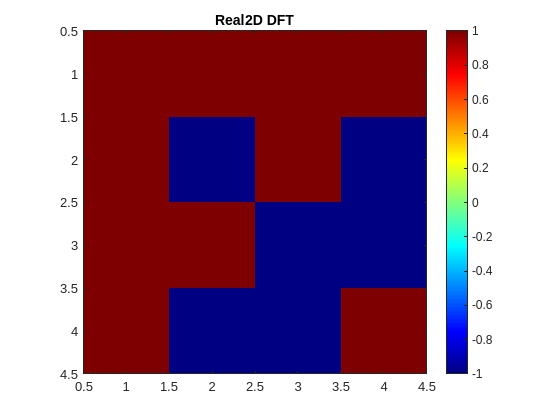


% Evaluating target 2D-DFT matrix F in Eq. (8) as
F = dft2_matrix(N_x, N_y);   % N_xN_y x N_xN_y, matches paper definition. [Eq. (11), 1]

figure
imagesc(real(F))
axis image
colormap jet
colorbar
title('Real{2D DFT}')

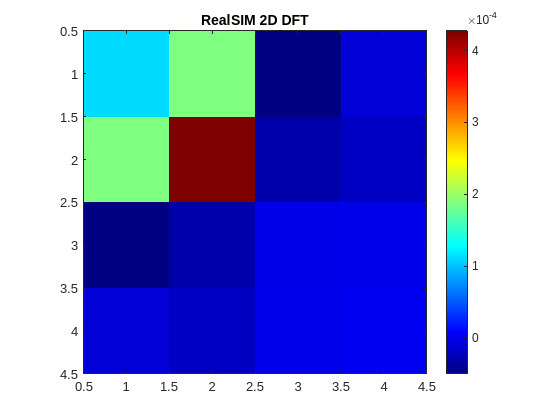


load G_matrix.mat
figure
imagesc(real(G))
axis image
colormap jet
colorbar
title('Real{SIM 2D DFT}')

%Parameters for testing
N_x=1
N_y=2
L=1
M_x=1
M_y=2


% -------------------- Build propagation matrices W0, Wl, WL --------------------
%Input layer
% W0: M x N (input layer -> layer 1), Eq. (6)
W0 = build_W0(M_x, M_y, N_x, N_y, s_x, s_y, d_x, d_y, s_layer, waveform_k, A_atom);

%Intermediate layer
% Wl: M x M for l=1..L-1 (between intermediate layers)
W = cell(L-1,1);
for l = 1:(L-1)
    W{l} = build_W_MM(M_x, M_y, s_x, s_y, s_layer, waveform_k, A_atom); % same each hop if geometry constant
end

%Output layer
% WL: N x M (layer L -> output layer)
WL = W0.';   % paper in [2] before Eq. (14) notes WL = W0^T under isomorphic arrangement


% ----- angle grid -----
Nphi = 80;                 % resolution per dimension
phi1 = linspace(0,2*pi,Nphi);
phi2 = linspace(0,2*pi,Nphi);

[PHI1, PHI2] = meshgrid(phi1, phi2);
Loss = zeros(Nphi, Nphi);



% ----- sweep -----
for i = 1:Nphi
    for j = 1:Nphi
        xi = cell(1,1);          % L = 1
        xi{1} = [PHI1(i,j); PHI2(i,j)];   % M = 2

        Loss(i,j) = loss_from_xi(xi, WL, W, W0, F);
    end
end

function F = dft2_matrix(Nx, Ny)
% Matches eq. (11): F(n,nhat) = exp(-j2pi (nx-1)(nhx-1)/Nx) * exp(-j2pi (ny-1)(nhy-1)/Ny)
    N = Nx*Ny;
    F = zeros(N,N);
    for n = 1:N
        [nx, ny] = ind2sub([Nx, Ny], n); % careful: Matlab ind2sub uses column-major; we want nx fastest
        % We'll define our own mapping: nx = mod(n-1,Nx)+1, ny = floor((n-1)/Nx)+1
        nx = mod(n-1, Nx) + 1;
        ny = floor((n-1)/Nx) + 1;
        for nh = 1:N
            nhx = mod(nh-1, Nx) + 1;
            nhy = floor((nh-1)/Nx) + 1;
            F(n,nh) = exp(-1j*2*pi*(nx-1)*(nhx-1)/Nx) * exp(-1j*2*pi*(ny-1)*(nhy-1)/Ny);
        end
    end
end

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function Lval = loss_from_xi(xi, WL, W, W0, F)

    % Forward model
    [G, ~] = forward_G(WL, W, W0, xi);

    % Optimal beta (Eq. 21)
    g = G(:);
    f = F(:);
    beta = (g' * f) / (g' * g);

    % Loss (Eq. 12)
    E = beta*G - F;
    Lval = norm(E,'fro')^2;
end

function [G, Gamma] = forward_G(WL, W, W0, xi)
    % This function evaluates all the products of Gamma_l*W_l as follows from Eq. (2)
    % Construct Gamma matrices and forward multiply to get G.
    L = numel(xi);
    Gamma = cell(L,1);
    
    %Evaluates the Gamma matrix per layer as follows from Eq. (3)
    for l = 1:L
        Gamma{l} = diag(exp(1j*xi{l}));
    end
    
    %Evaluates the multiplication Gamma_l*W_l
    X = W0;
    for l = 1:(L-1)
        X = W{l} * Gamma{l} * X;
    end
    X = Gamma{L} * X;
    G = WL * X;
    
    
end